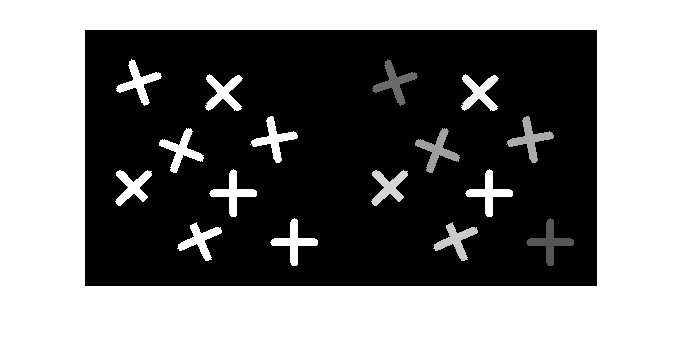

%%Task 01
img = imread('crosses.gif');
img1 = imread('crosses.gif');

%draw white crosses
cc = bwconncomp(img, 8);
for i=1:length(cc.PixelIdxList)
    img(cc.PixelIdxList{i}) = 255;
end

%random numbers between 10-50
n = 20;
R = [10 50];
x = rand(n,1)*range(R)+min(R);


%draw grey crosses
cc = bwconncomp(img, 8);
for i=1:length(cc.PixelIdxList)
    img1(cc.PixelIdxList{i}) = x(i);
end
imshowpair(img, img1, 'montage')

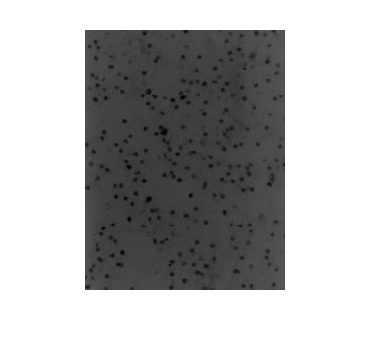

%Task 2

img2 = imread('nervous_cells.gif');
imshow(img2);

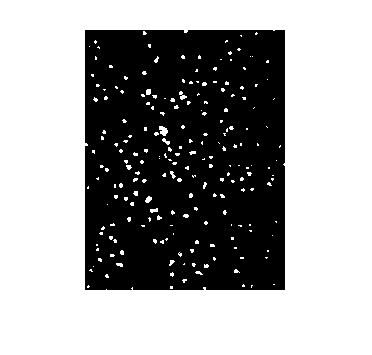

img3 = imbinarize(img2, 0.16);
img4 = imcomplement(img3);
imshow(img4)

cc2 = bwconncomp(img4, 4)

cc2 = struct with fields:
    Connectivity: 4
       ImageSize: [260 200]
      NumObjects: 220
    PixelIdxList: {1×220 cell}


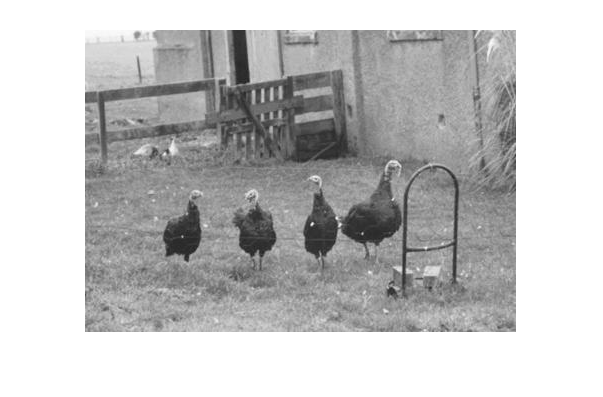

%Task3
SE = strel('rectangle', [10 10]);
SE1 = strel('disk', 10);
SE2 = strel('rectangle', [2 2]);
SE3 = strel('rectangle', [3 12]);
SE4 = strel('disk', 5);
img5 = imread('turkeys.jpg');
imshow(img5);

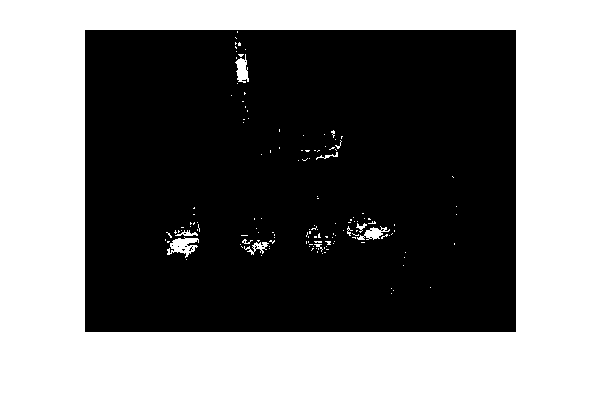

img6 = imbinarize(img5, 0.19);
img7 = imcomplement(img6);
imshow(img7)

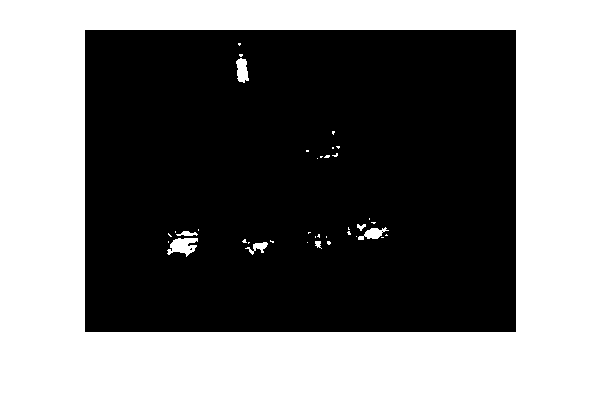

img8 = medfilt2(img7);
imshow(img8)

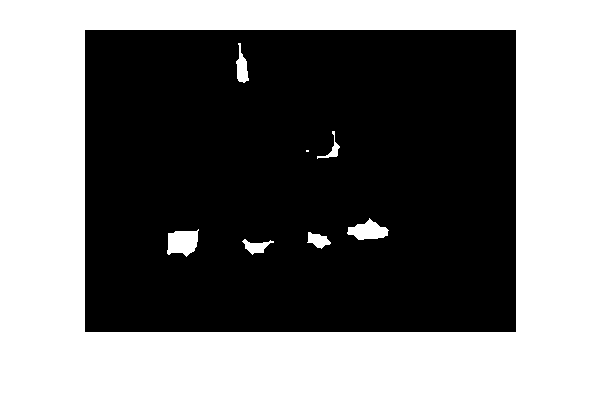

img9 = imclose(img8,SE1);
imshow(img9)

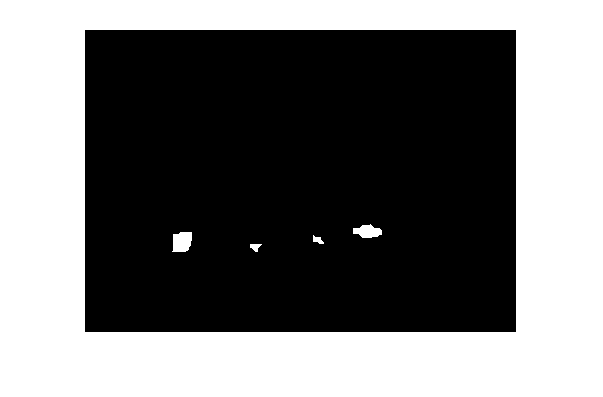

img10 = imerode(img9, SE3);
imshow(img10)

cc3 = bwconncomp(img10, 8)

cc3 = struct with fields:
    Connectivity: 8
       ImageSize: [302 431]
      NumObjects: 4
    PixelIdxList: {[342×1 double]  [60×1 double]  [57×1 double]  [277×1 double]}
